clear all;
close all;
clc;

% SEM HJ116J6-130S 
% R = 0.85;
% L = 4.75e-3;
% p = 6;
% iph_max = 7.8;
% vph_max = 286;

% SEM HJ130G8-130S
R = 0.75;
L = 3.15e-3;
p = 8;

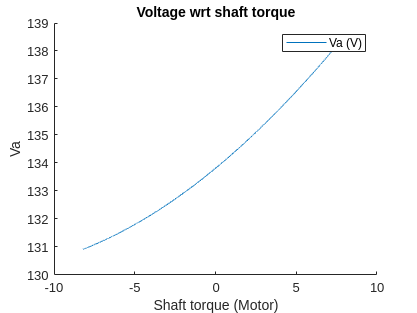

% Calculate model
% 4.4
beta = 0;
ia = -5:0.001:5; % armature current

omega_m = 2*pi*2400/60;
omega_e = omega_m*p/2; % electric omega
lambda_m = 0.133;

% Electrical characteristics
ef = lambda_m * omega_e;
va = ef + ia * (R + i*omega_e*L);

% Torque
% tf_tot = 0.001638 * omega_m + 0.4942;

tf_tot = 0.002401 * omega_m + 0.5246;
tf_pmsm = 0.2 * tf_tot;
td = 3*ef*ia*cos(beta)/omega_m;
ts = td - tf_pmsm;


% Motor
ts_new = (td-tf_pmsm);
% ts_new(ts_new == 0) = NaN;

figure;
hold on;
plot(ts_new, abs(va));

title('Voltage wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

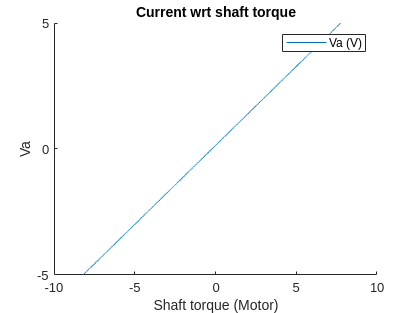


figure;
hold on;
plot(ts_new, ia);
title('Current wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

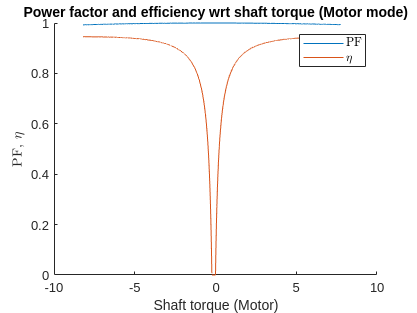


% 5
PF = cos(angle(va));
% Motor
eff = (ts > 0).*(td > 0).*(ts*omega_m)./abs(3*va.*ia.*PF);
% Generator
eff = eff + (ts < 0).*(td < 0).*abs(3*va.*ia.*PF)./abs(ts*omega_m);
figure;
hold on;
plot(ts_new, PF);
plot(ts_new, eff);
title('Power factor and efficiency wrt shaft torque (Motor mode)');
xlabel('Shaft torque (Motor)');
ylabel('PF, $\eta$', 'Interpreter', 'latex');
legend('PF', '$\eta$', 'Interpreter', 'latex');
hold off;

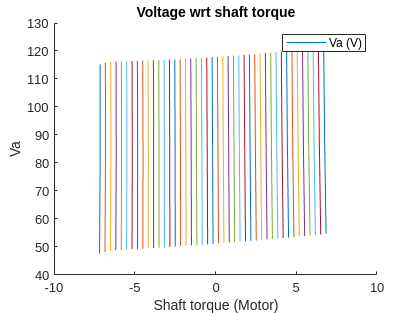

% Calculate - Actual

Ns = 43;
s = 3; % time step

load('Measurement_Data/Measurement_2023_12_14_16_46.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(1, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(1, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(1, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(1, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(1, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(1, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_16_50.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(2, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(2, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(2, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(2, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(2, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(2, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_16_54.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(3, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(3, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(3, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(3, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(3, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(3, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end

ia = Ia_ACM_filtered; % armature current

omega_m = 2*pi*n_filtered;
omega_e = omega_m*p/2; % electric omega
lambda_m = 0.133;

% Electrical characteristics
% ef = lambda_m * omega_e;
% va = ef + ia * (R + i*omega_e*L);

va = Van_ACM_filtered.*exp(1i.*acos(PF_ACM_filtered));
ef = va - ia.*(R + 1i.*omega_e*L);
% Torque
% tf_tot = 0.001638 * omega_m + 0.4942;

beta = angle(ef);
tf_tot = 0.002401 * omega_m + 0.5246;
tf_pmsm = 0.2 * tf_tot;
td = 3*abs(ef).*ia.*cos(angle(ef))./omega_m;
ts = td - tf_pmsm;


% Motor
ts_new = (td-tf_pmsm);
% ts_new(ts_new == 0) = NaN;

figure;
hold on;
plot(ts_new, abs(va));

title('Voltage wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

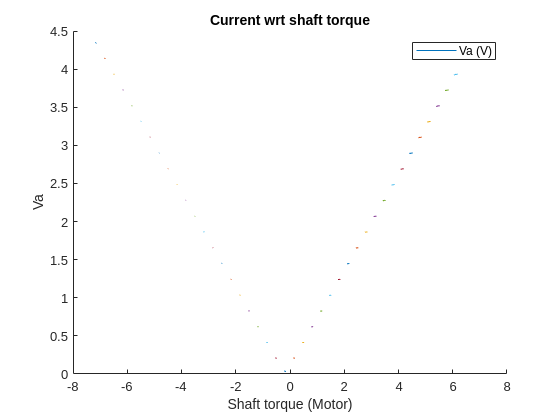


figure;
hold on;
plot(ts_new, ia);
title('Current wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;


% 5
% PF = cos(angle(va));
% Motor
eff = (ts > 0).*(td > 0).*(ts.*omega_m)./abs(3*va.*ia.*PF);

Arrays have incompatible sizes for this operation.

Related documentation

% Generator
eff = eff + (ts < 0).*(td < 0).*abs(3*va.*ia.*PF)./abs(ts.*omega_m);
figure;
hold on;
plot(ts_new, PF);
plot(ts_new, eff);
title('Power factor and efficiency wrt shaft torque (Motor mode)');
xlabel('Shaft torque (Motor)');
ylabel('PF, $\eta$', 'Interpreter', 'latex');
legend('PF', '$\eta$', 'Interpreter', 'latex');
hold off;